# audioFeatureExtractorによる異音判定

以下では、1つの健全な状態と7つの異なる異常の状態を有する空気圧縮機の異音判定のアルゴリズムを示しています。

音声データはいずれも16 kHzで取得されています。

[https://jp.mathworks.com/help/audio/ref/yamnet.html](https://jp.mathworks.com/help/audio/ref/yamnet.html)

デモに必要な製品一覧：

- Audio Toolbox™

- DSP System Toolbox™

- Signal Processing Toolbox™

- Statistics and Machine Learning Toolbox™

## 初期化

clear; close all;
format short; format compact;
% 乱数群の制御
rng('default');

## データの読み込み

filepath = 'C:\Users\xwang\OneDrive - MathWorks\06_Presentation\05_Demos\00_dataset\03_airCompressor\AirCompressorDataSet';
ads = audioDatastore(filepath,'IncludeSubfolders',true,...
    'LabelSource','foldernames'); %* フォルダ名 = ラベル

## データの分割：学習用 + 検証用 + テスト用

ads = shuffle(ads);
[adsTrain,adsValidation,adsTest] = splitEachLabel(ads,0.7,0.2,0.1);

## データの構成を確認：学習用 + 検証用 + テスト用

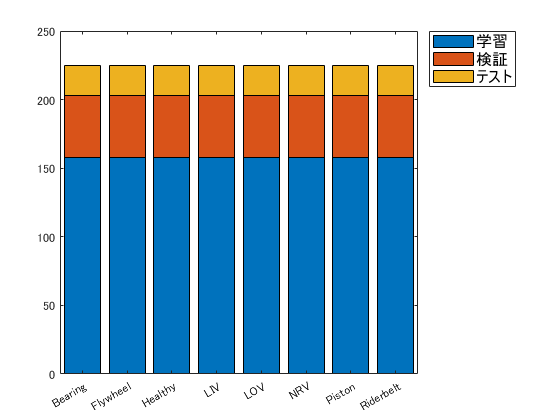

uniqueLabels = unique(ads.Labels);
tblTrain = countEachLabel(adsTrain);
tblValidation = countEachLabel(adsValidation);
tblTest = countEachLabel(adsTest);
H = bar(uniqueLabels,[tblTrain.Count, tblValidation.Count, tblTest.Count],'stacked');
legend(H,{'学習','検証','テスト'},'Location','NorthEastOutside','FontSize',12)

## 可視化

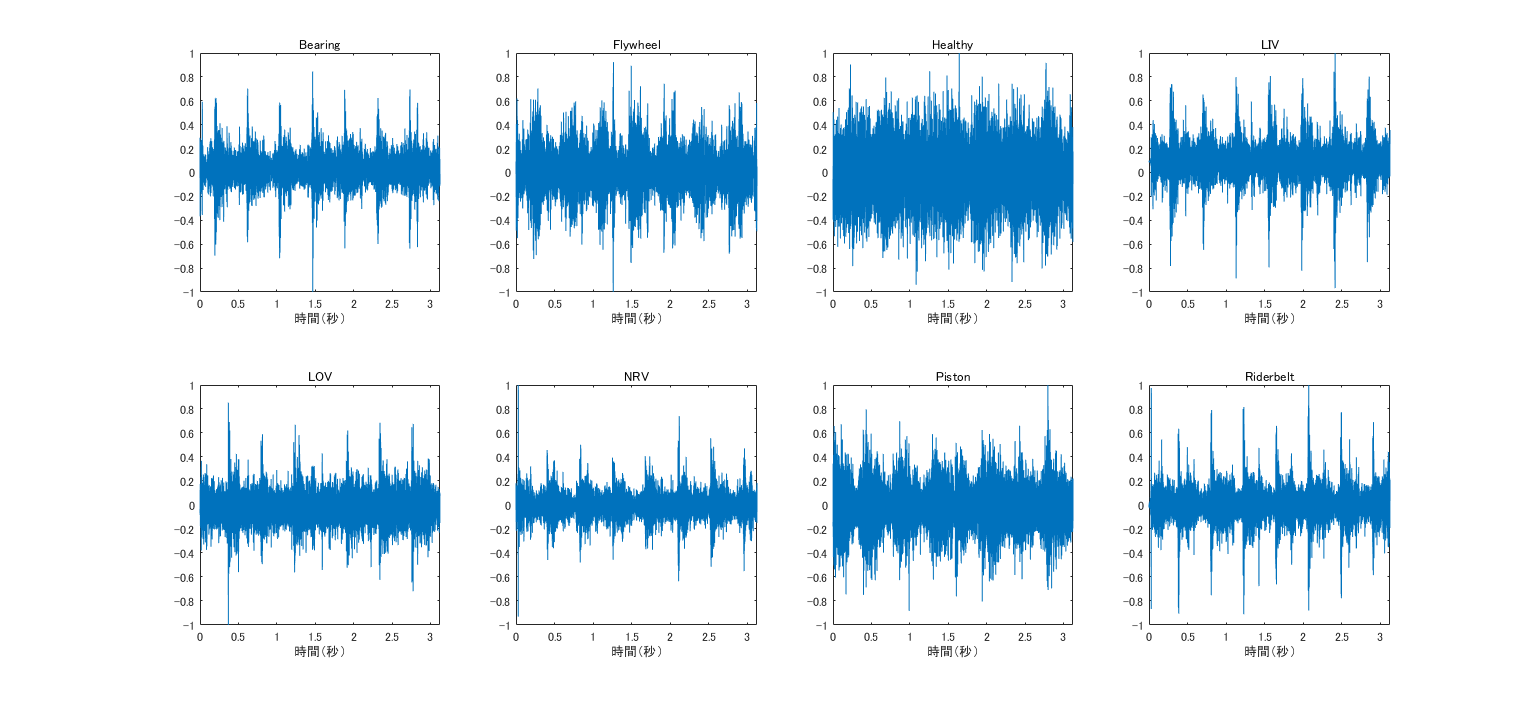

figure('Name','Imported data','Units','Normalized','Position',[0.05, 0.25, 0.80, 0.65]);
for n = 1:numel(uniqueLabels)
    idx = find(adsTrain.Labels==uniqueLabels(n),1);
    [x,fs] = audioread(adsTrain.Files{idx});
    
    t = (0:size(x,1)-1)/fs;
    
    subplot(2,4,n);
    plot(t,x);
    xlabel('時間（秒）')
    title(string(uniqueLabels(n)));
end

## 特徴抽出：

コマンドライン、または、タスクからExtract Audio Featuresを活用

afe = audioFeatureExtractor("SampleRate",fs, ...
    "mfcc",true,"spectralCentroid",true, ...
    "spectralCrest",true,"spectralEntropy",true, ...
    "spectralFlatness",true,"spectralFlux",true, ...
    "spectralKurtosis",true);

## 学習用

m = 50;
cumval = cumsum(tblTrain.Count);
idx = [randperm(tblTrain.Count(1), m),...
    randperm(tblTrain.Count(2),m)+cumval(1),...
    randperm(tblTrain.Count(3),m)+cumval(2),...
    randperm(tblTrain.Count(4),m)+cumval(3),...
    randperm(tblTrain.Count(5),m)+cumval(4),...
    randperm(tblTrain.Count(6),m)+cumval(5),...
    randperm(tblTrain.Count(7),m)+cumval(6),...
    randperm(tblTrain.Count(8),m)+cumval(7)];

labels = adsTrain.Labels;
adsTrain.Files = adsTrain.Files(idx);
adsTrain.Labels = labels(idx);

trainFeatures = [];
trainLabels = adsTrain.Labels;
trainLabels(:) = [];
reset(adsTrain);

tic
while hasdata(adsTrain)
    [audioIn,fileInfo] = read(adsTrain);
    features = extract(afe,audioIn);
    trainFeatures = cat(1,trainFeatures,features);
    
    label = repelem(fileInfo.Label,size(features,1));
    label = label(:); % column vector
    trainLabels = cat(1,trainLabels, label);
end
toc

経過時間は 5.620082 秒です。


% trainTbl = [array2table(trainFeatures),table(trainLabels)];

features0 = zscore(trainFeatures,0,1);
trainTbl = [array2table(features0),table(trainLabels)];

## 検証用

validationFeatures = [];
validationLabels = adsValidation.Labels;
validationLabels(:) = [];
reset(adsValidation);

tic
while hasdata(adsValidation)
    [audioIn,fileInfo] = read(adsValidation);
    features = extract(afe,audioIn);
    validationFeatures = cat(1,validationFeatures,features);
    
    label = repelem(fileInfo.Label,size(features,1));
    label = label(:); % column vector
    validationLabels = cat(1,validationLabels,label);
end
toc

経過時間は 4.716820 秒です。


% validationTbl = [array2table(validationFeatures),table(validationLabels)];

features0 = zscore(validationFeatures,0,1);
validationTbl = [array2table(features0),table(validationLabels)];

## テスト用

testFeatures = [];
testLabels = adsTest.Labels;
testLabels(:) = [];
reset(adsTest);

tic
while hasdata(adsTest)
    [audioIn,fileInfo] = read(adsTest);
    features = extract(afe,audioIn);
    testFeatures = cat(1,testFeatures,features);
    
    label = repelem(fileInfo.Label,size(features,1));
    label = label(:); % column vector
    testLabels = cat(1,testLabels, label);
end
toc

経過時間は 2.170760 秒です。


% testTbl = [array2table(testFeatures),table(testLabels)];

features0 = zscore(testFeatures,0,1);
testTbl = [array2table(features0),table(testLabels)];

## データの保存

% save featureTable_audioFeatureExtractorML_v01.mat trainTbl validationTbl testTbl % データの保存

## 分類学習器

KNNモデルで約66%の精度。

classificationLayer;

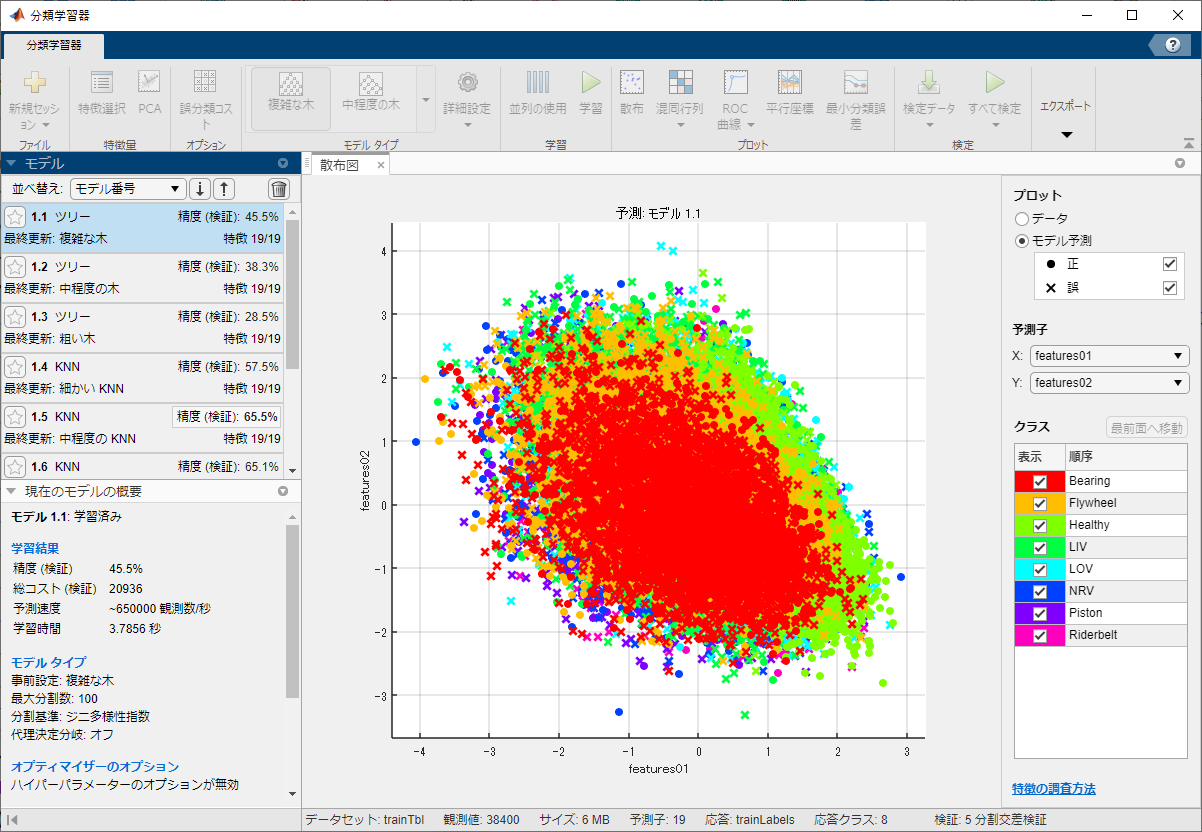

*Copyright 2021 The MathWorks, Inc.*